# 交互教学 01：配电网时序潮流与节点电压

本节研究辐射状配电网在 24 小时内的电压变化。三个光伏节点各接入 0.8 MW 光伏，不配置储能。

## 使用方法

先将 MATLAB 当前文件夹切换到 interactive。首次点击“全部运行”。修改计算参数后重新运行；查看时段、支路或节点的滑块只更新所在节的图形。

lesson = ess_live_setup();
export_figures = true;

## 个人学号与本次计算条件

修改学号后重新运行后续各节。算例、负荷系数和候选节点沿用课程统一规则。

Stu_ID = 242400002;
XY=mod(Stu_ID,100);
X_digit=floor(XY/10); Y_digit=mod(XY,10);
alpha=1+0.002*XY;
if ismember(Y_digit,[0 1 2 3])
    case_name='case_nongcun';
elseif ismember(Y_digit,[4 5 6])
    case_name='case_chengshi_A';
else
    case_name='case_kaifaqu_A';
end
if ismember(X_digit,[0 1 2])
    study_buses=[4 9 14]; model_type='A';
elseif ismember(X_digit,[3 4 5])
    study_buses=[5 11 16]; model_type='B';
else
    study_buses=[6 13 17]; model_type='C';
end
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T; dt=1;
load_curve_pu=profiles.load_curve_pu; pv_curve_pu=profiles.pv_curve_pu;
price_MWh=profiles.price_MWh; price_kWh=profiles.price_kWh;
disp(table(Stu_ID,string(case_name),alpha,string(model_type),string(mat2str(study_buses)),...
    'VariableNames',{'StudentID','Case','LoadMultiplier','Objective','StudyNodes'}));

    StudentID         Case         LoadMultiplier    Objective    StudyNodes
    _________    ______________    ______________    _________    __________

    2.424e+08    "case_nongcun"        1.004            "A"       "[4 9 14]"



mpc_base=loadcase(case_name);
pv_buses=study_buses;

## 负荷与光伏参数

功率使用 MW、Mvar，支路阻抗使用标幺值，节点电压使用标幺值。算例已完成阻抗换算。修改演示负荷系数后重新运行。

load_multiplier = 1;
alpha=(1+0.002*XY)*load_multiplier;
P_pv_peak_MW=0.8;

## 查看节点数据

节点有功与无功负荷分别位于第 3、4 列。先查看前十个节点，再确认光伏接入位置。

disp(array2table(mpc_base.bus(1:min(10,end),[1 3 4 10]),'VariableNames',{'Node','Load_MW','Load_Mvar','Base_kV'}));

    Node    Load_MW    Load_Mvar    Base_kV
    ____    _______    _________    _______

      1          0           0       12.66 
      2      0.122        0.03       12.66 
      3          0           0       12.66 
      4      0.075       0.019       12.66 
      5          0           0       12.66 
      6      0.065       0.016       12.66 
      7      0.025       0.006       12.66 
      8      0.017       0.004       12.66 
      9      0.042       0.011       12.66 
     10      0.038        0.01       12.66 



## 构造逐时负荷并计算交流潮流

各时段均从基准算例重新构造负荷，光伏有功从节点负荷中扣除。


$$P_{i,t}^{\mathrm{net}}=\alpha P_{i,0}^{\mathrm{load}}p_t^{\mathrm{load}}-P_{i,t}^{\mathrm{pv}}$$


N_bus      = size(mpc_base.bus, 1);
V_bus_24h  = zeros(N_bus, T);
P_loss_24h = zeros(T, 1);
mpopt      = mpoption('verbose', 0, 'out.all', 0);
for t = 1:T
    mpc_t = mpc_base;
    mpc_t.bus(:, 3) = mpc_base.bus(:, 3) * alpha * load_curve_pu(t);
    mpc_t.bus(:, 4) = mpc_base.bus(:, 4) * alpha * load_curve_pu(t);
    mpc_t.bus(pv_buses, 3) = mpc_t.bus(pv_buses, 3) - P_pv_peak_MW * pv_curve_pu(t);
    results = runpf(mpc_t, mpopt);
    assert(results.success==1,'第 %d 时段交流潮流未收敛。',t);
    V_bus_24h(:, t) = results.bus(:, 8);
    P_loss_24h(t)   = sum(real(get_losses(results)));
end

## 最低电压与全天电能损耗

输出最低电压及其节点、时段，并将逐时有功损耗对时间求和。


$$E_{\mathrm{loss}}=\sum_{t=1}^{T}P_{\mathrm{loss},t}\Delta t$$


[min_V,ix]=min(V_bus_24h(:));
[min_bus,min_hour]=ind2sub(size(V_bus_24h),ix);
DailyLoss_MWh=sum(P_loss_24h)*dt;
disp(table(min_V,min_bus,min_hour,DailyLoss_MWh));

     min_V     min_bus    min_hour    DailyLoss_MWh
    _______    _______    ________    _____________

    0.95653      13          19          0.99647   



## 交互查看节点电压

移动时段滑块，观察馈线上各节点电压；移动节点滑块，查看所选节点的全天电压。节点编号按当前算例范围取值。

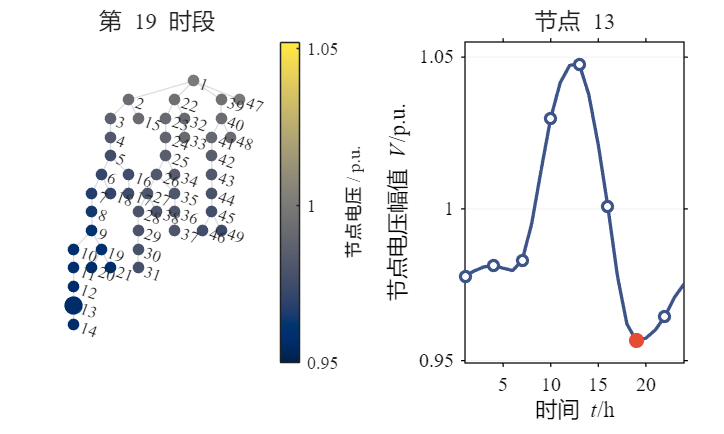

view_hour = 19;
view_node = 13;
view_node=min(view_node,N_bus);
fig_voltage=ess_live_view('voltage',mpc_base,V_bus_24h,view_hour,view_node);

## 保存本次课堂结果

导出到 interactive/results，不覆盖原始脚本的图形文件。

out_dir=fullfile(lesson.results,sprintf('Lesson01_%d',Stu_ID));
if export_figures, ess_live_export(fig_voltage,out_dir,'Voltage_Explorer'); end

Lesson_Stats=struct('Lesson',1,'MinVoltage',min_V,'DailyLoss_MWh',DailyLoss_MWh);

## 练习

将附加负荷倍率由 1.00 调整为 1.10。计算前先判断最低电压和电能损耗如何变化；计算后记录节点、时段和数值，并解释变化原因。